clearvars
close all

% Definindo as constantes
m = 188.6; % Massa do ROV
I_z = 40.50; % Momento de inércia ao redor de Z

m_u = 450.87; % Massa virtual na direção X
m_v = 558.92; % Massa virtual na direção Y
I_r = 239.44; % Momento virtual ao redor de Z

% Coeficientes de arrasto hidrodinâmico
K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

% Definindo as velocidades de equilíbrio:
U = 0.5;
V = 0.5;
R = 0.126;

Matrizes

Matrizes

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v); 
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];


B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];

D = zeros(1,3);

E = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r]; 

B_novo = [B E];

D_novo = [D zeros(size(C,1),size(E,1))];



Criação das funções de transferência do sistema

[num1, den1] = ss2tf(A, B, C, D, 1);
[num2, den2] = ss2tf(A, B, C, D, 2);
[num3, den3] = ss2tf(A, B, C, D, 3);

tf11 = tf(num1(1, :), den1(1, :));  
tf12 = tf(num2(1, :), den2(1, :));   
tf13 = tf(num3(1, :), den3(1, :));   

dt = 0.1;
t_ = 0:dt:150;

DISTURBIO

w1 = zeros(size(t_));

for i = 1:1:50
    w1(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 51:1:56
    w1(i) = 5*sin(2*pi()*0.1*t_(i))+ 2000;
end
for i = 57:1:350
    w1(i) = 5*sin(2*pi()*0.1*t_(i));
end
for i = 351:1:356
    w1(i) = 5*sin(2*pi()*0.1*t_(i)) - 400;
end
for i = 357:1:601
    w1(i) = 5*sin(2*pi()*0.1*t_(i));
end
w2 = 10*sin(2*pi()*0.1*t_);

w3 = zeros(1, length(t_));


rlocus

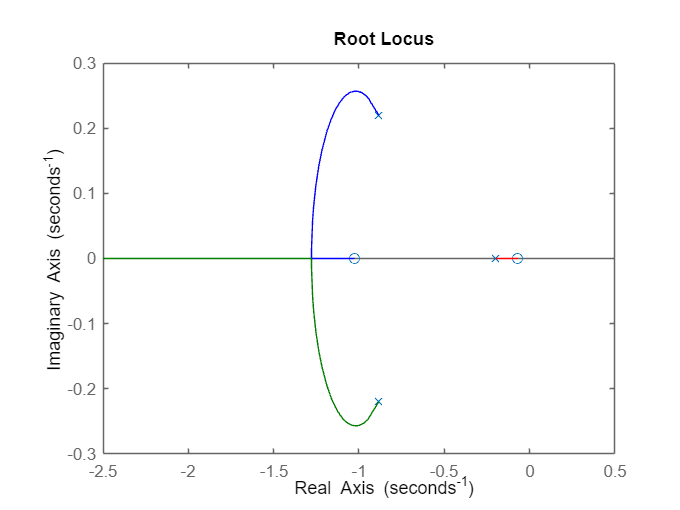

figure(1)
rlocus(tf11)

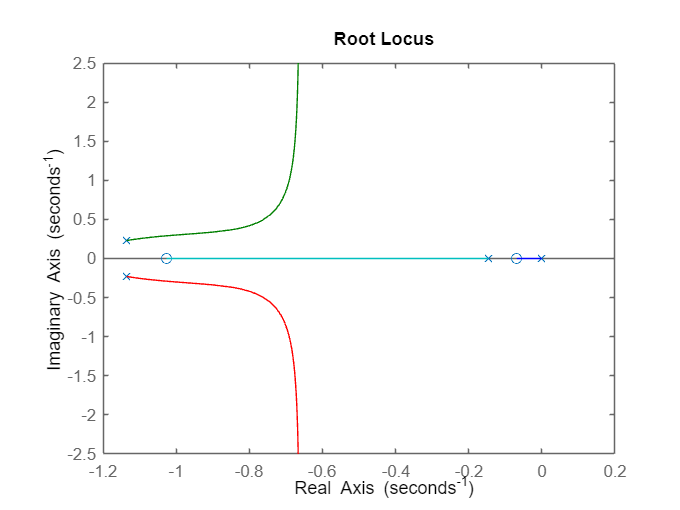

Kp = 204;
%[k, poles] = rlocfind(tf11);

% Determinando Ki
N2 = num1(1, :);
D2 = [den1(1, :) + Kp * [num1(1, :)] 0];
GH2 = tf(N2, D2);


figure(2)
rlocus(GH2)

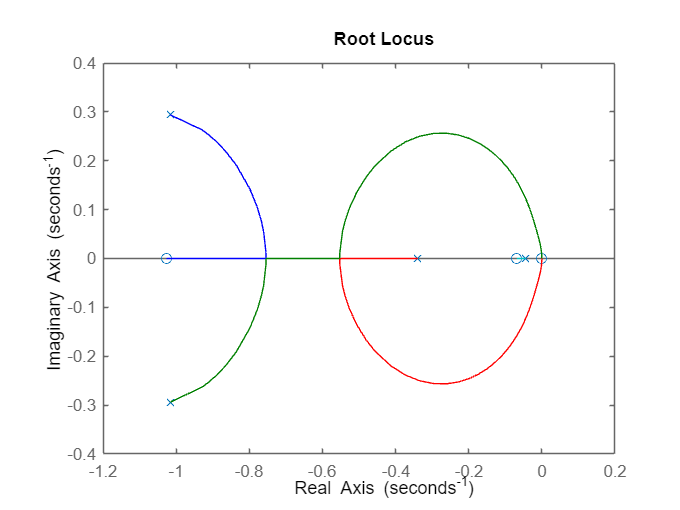

%rlocfind(GH2)
Ki = 109;

% Determinando o Kd
N3 = [num1(1, :) 0 0];
D3 = [den1(1, :) 0] + conv([Kp Ki], num1(1, :));
GH3 = minreal(tf(N3, D3));

figure(3)
rlocus(GH3)

%rlocfind(GH3)
Kd = 828;

Controlador

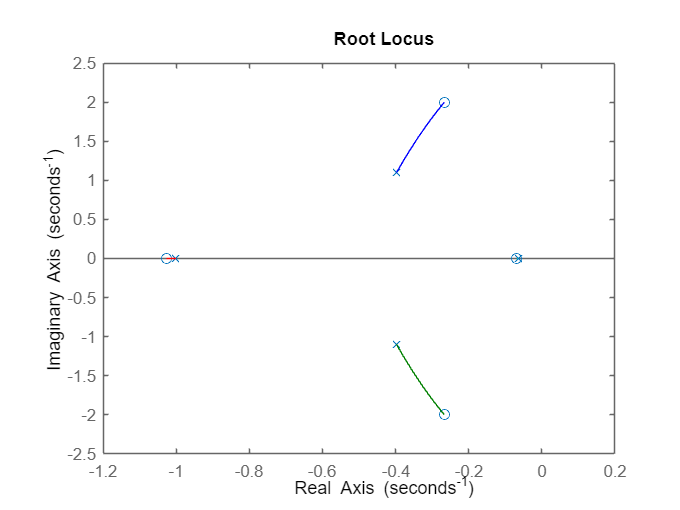

N_pid = [Kp Ki Kd];
D_pid = [1 0];
PID = tf(N_pid, D_pid);

TF_PID = feedback(PID * tf11, 1);
rlocus(TF_PID);


Gd = feedback(tf11,PID);

ygd2 = lsim(Gd,w1,t_);
ygd= ygd2 + U;

y2 = lsim(tf11, w1, t_);
y = y2 + U;


Plots

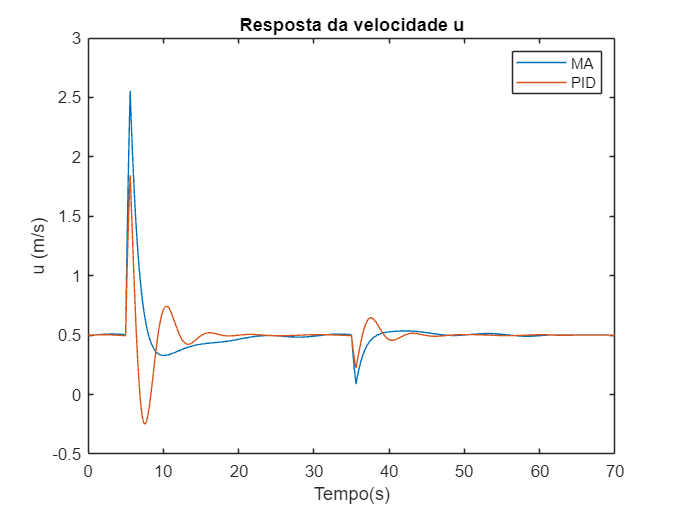

figure(1)
plot(t_, y)
hold on
plot(t_, ygd)
title('Resposta da velocidade u')
xlabel('Tempo(s)')
ylabel('u (m/s)')
xlim([0 70])
legend('MA', 'PID')
hold off

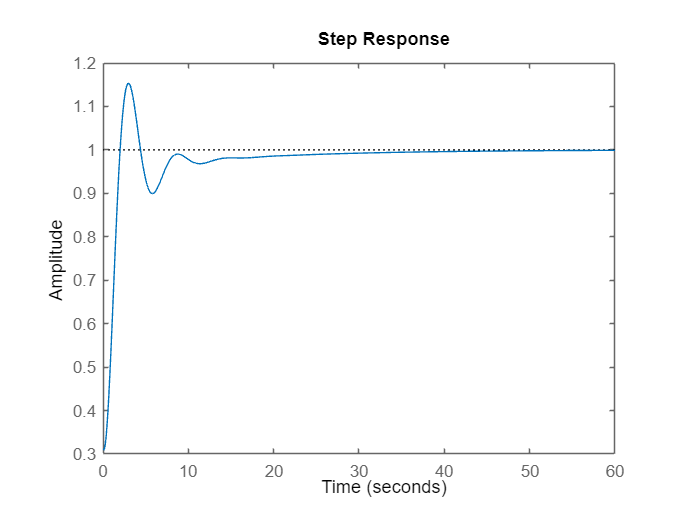


figure(2)
step(TF_PID)

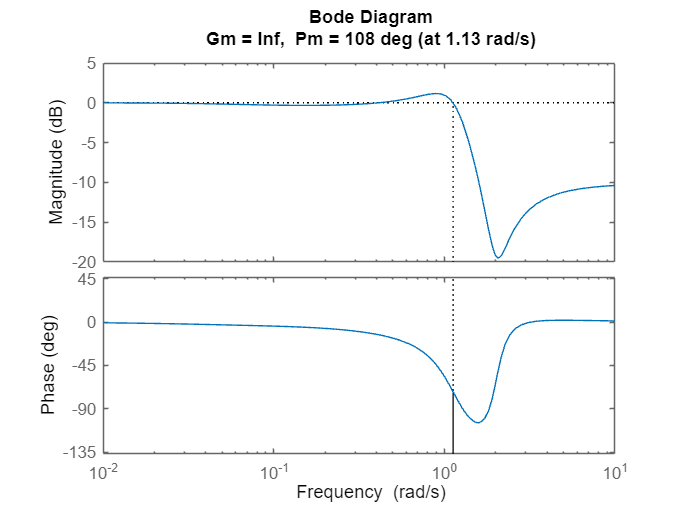


margin(TF_PID)